Matlab code for the Course: **Modelling and Simulation Mechatronics System**

by Enrico Bertolazzi and Francesco Biral

Dipartimento di Ingegneria Industriale

Università degli Studi di Trento

email: [enrico.bertolazzi@unitn.it](mailto:enrico.bertolazzi@unitn.it)

### Initialize by cleaning memory and widows

clear all;
close all;

### **Load the Pendulum model ODE**

% load the Pendulum model in the variable ode
ell     = 2;
gravity = 9.81;
ode     = Pendulum5EQ( ell, gravity );

### Initialize 3 solver for comparison

solver_H  = Heun();
solver_H3 = Heun3();
solver_CN = CrankNicolson();

solver_H.setODE(ode);
solver_H3.setODE(ode);
solver_CN.setODE(ode);

### Set time step and inital conditions for solvers

Tmax = 10;
h    = 0.05;
tt   = 0:h:Tmax;
% setup initial condition
theta0  = pi/2;
omega0  = 0;
x0      = ell*sin(theta0);
y0      = -ell*cos(theta0);
u0      = 0;
v0      = 0;
lambda0 = -(y0*gravity+u0^2+v0^2)/(x0^2+y0^2);
ini     = [x0;y0;u0;v0;lambda0];

### Compute solutions

sol_H  = solver_H.advance( tt, ini );
sol_H3 = solver_H3.advance( tt, ini );
sol_CN  = solver_CN.advance( tt, ini );

### Extract computed solution

x_H = sol_H(1,:);
y_H = sol_H(2,:);

x_H3 = sol_H3(1,:);
y_H3 = sol_H3(2,:);

x_CN = sol_CN(1,:);
y_CN = sol_CN(2,:);

### Plot computed solution

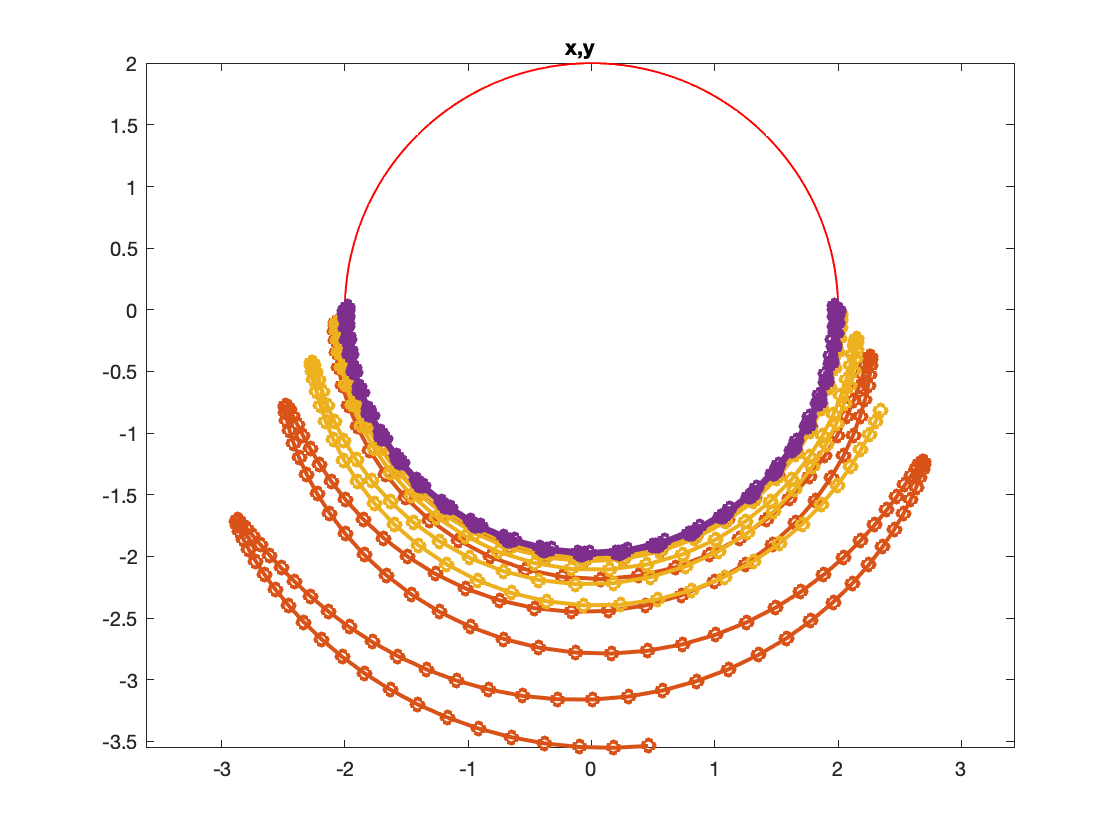

h = figure();
xx = ell*cos(0:pi/100:2*pi);
yy = ell*sin(0:pi/100:2*pi);
plot( xx, yy, '-r', 'Linewidth', 1 );
hold on
axis equal
plot( x_H,  y_H,  '-o', 'MarkerSize', 6, 'Linewidth', 2 );
plot( x_H3, y_H3, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
plot( x_CN, y_CN, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
title('x,y');

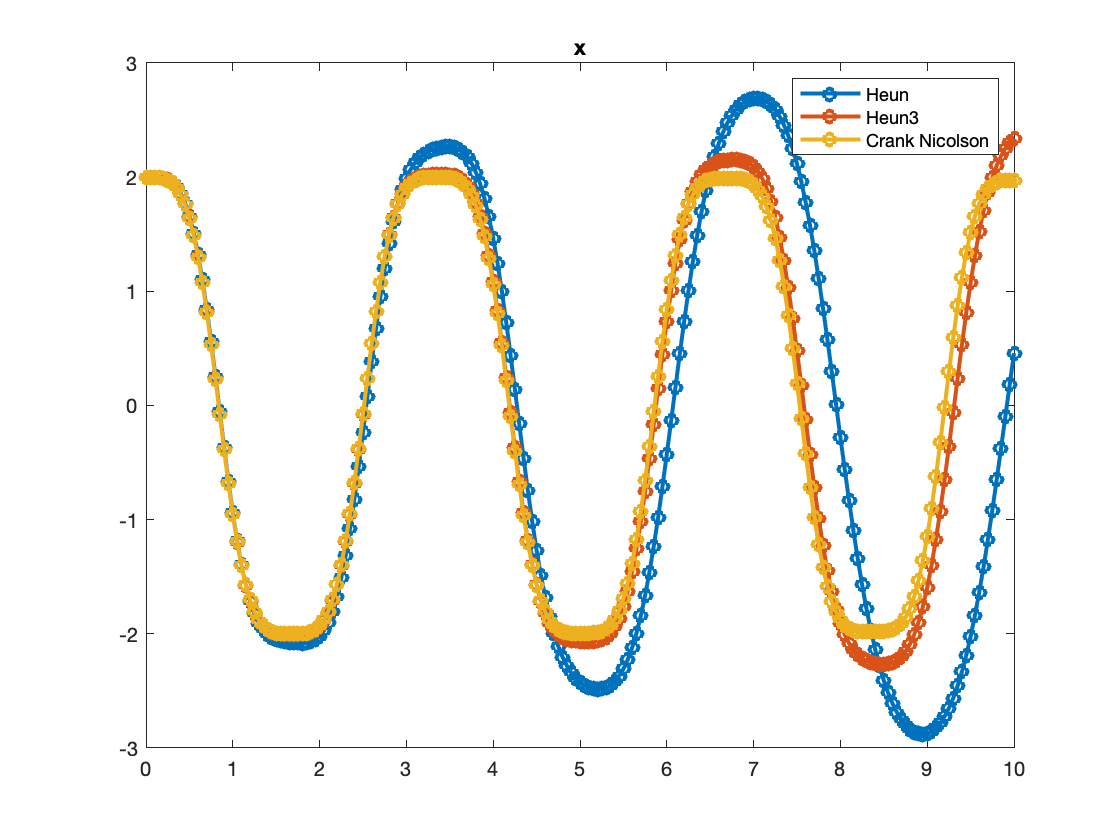

h = figure();
plot( tt, x_H, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
hold on;
plot( tt, x_H3, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
plot( tt, x_CN, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
legend({'Heun', 'Heun3','Crank Nicolson'});
title('x');

### Make animation of the solution

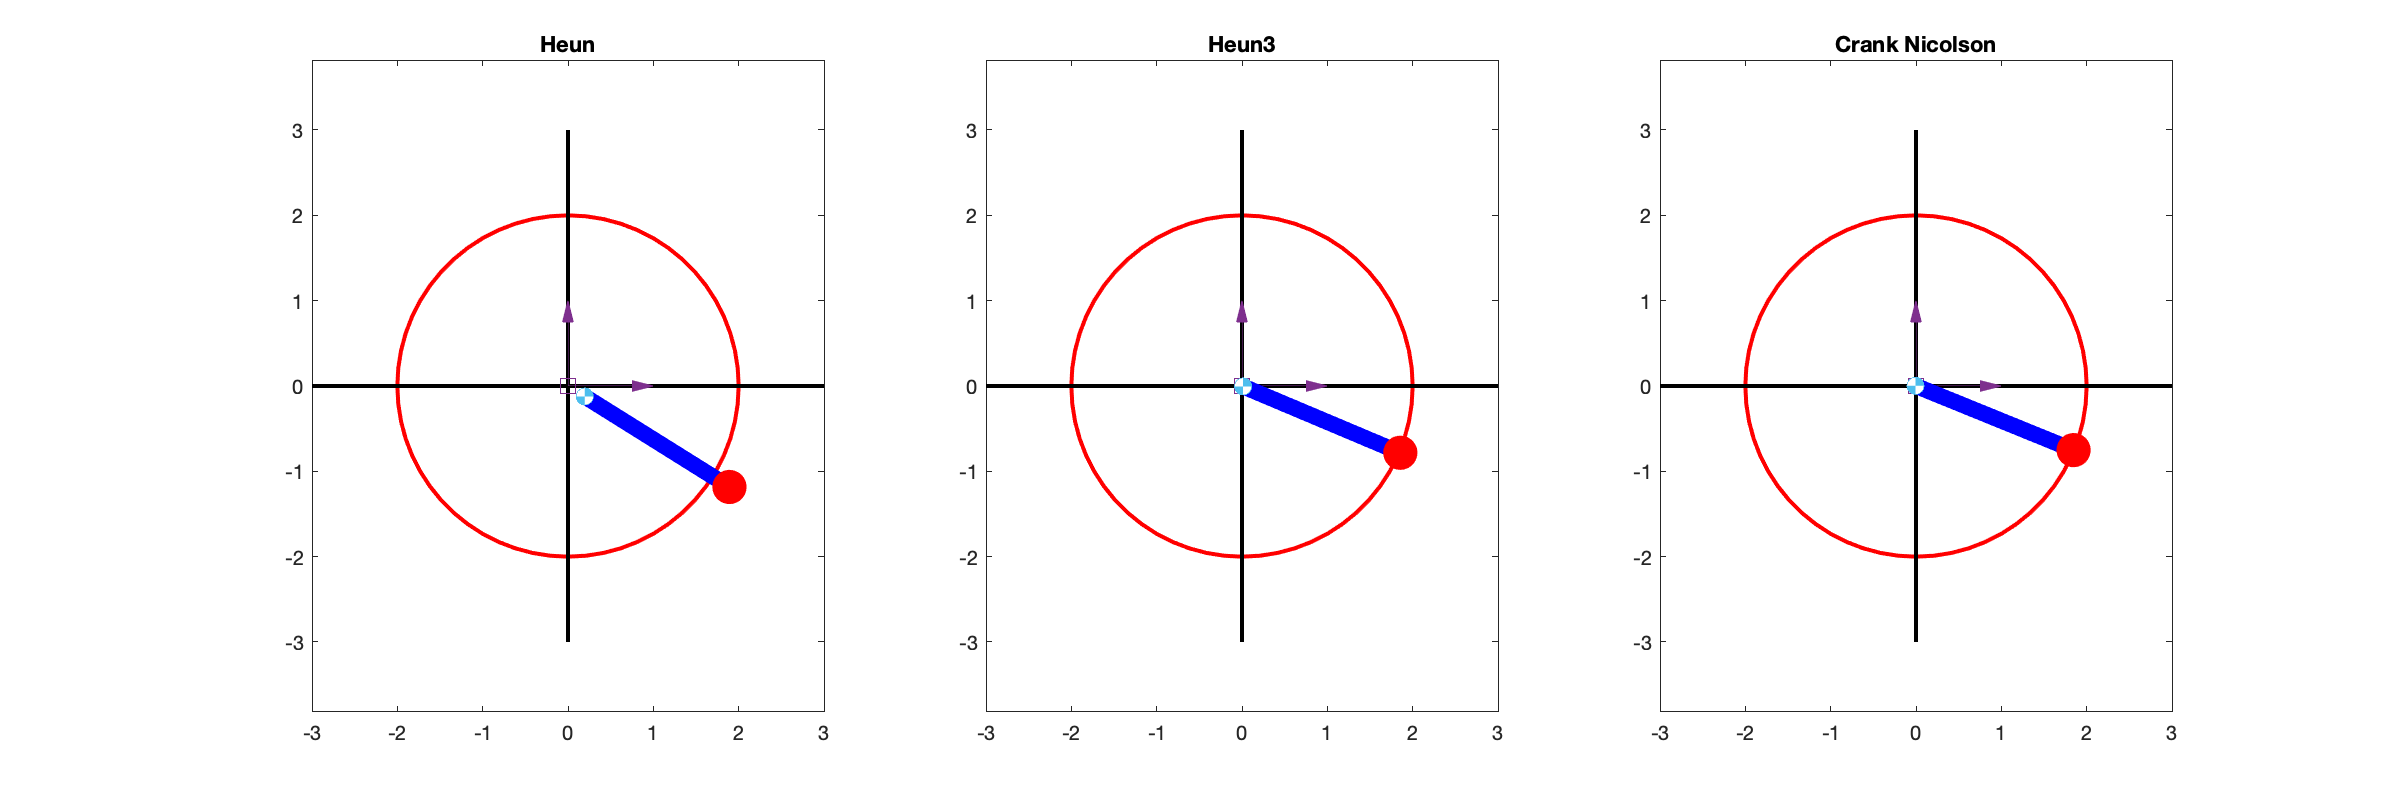

figure('Position', [10 10 1200 400]);
for k=1:length(tt)
  subplot(1,3,1);
  ode.plot( tt(k), sol_H(:,k));
  title('Heun');
  subplot(1,3,2);
  ode.plot( tt(k), sol_H3(:,k));
  title('Heun3');
  subplot(1,3,3);
  ode.plot( tt(k), sol_CN(:,k));
  title('Crank Nicolson');
  drawnow limitrate;
  pause(0.01);
end